# Week 2 Assignment - Handwritten digit classification

## Since MATLAB does not have the datasets built in we need to download and preprocess them.

1. download training and testing datasets

set url addresses for training and test datasets and labels

trainingDatasetUrl = 'http://yann.lecun.com/exdb/mnist/train-images-idx3-ubyte.gz';
trainingLabelsUrl = 'http://yann.lecun.com/exdb/mnist/train-labels-idx1-ubyte.gz';
testDatasetUrl = 'http://yann.lecun.com/exdb/mnist/t10k-images-idx3-ubyte.gz';
testLabelsUrl = 'http://yann.lecun.com/exdb/mnist/t10k-labels-idx1-ubyte.gz';

set output filenames

trainingDatasetFilename = 'train-images-idx3-ubyte.gz';
trainingLabelsFilename = 'train-labels-idx1-ubyte.gz';
testDatasetFilename = 't10k-images-idx3-ubyte.gz';
testLabelsFilename = 't10k-labels-idx1-ubyte.gz';

save the datasets using `websave` function

websave(trainingDatasetFilename, trainingDatasetUrl);
websave(trainingLabelsFilename, trainingLabelsUrl);
websave(testDatasetFilename, testDatasetUrl);
websave(testLabelsFilename, testLabelsUrl);

unzip files for reading

files = gunzip('*.gz');

2. Preprocess the downloaded files

trainImages = readMnistDatasets(files{1});
trainLabels = categorical(squeeze(readMnistDatasets(files{2})));
testImages = readMnistDatasets(files{3});
testLabels = categorical(squeeze(readMnistDatasets(files{4})));

## Build Convolutional Neural Network Model

- there is no need for `flatten layer `between maxpooling and fully connected. MATLAB takes care of that behind the scene

layers = [...
    imageInputLayer(size(trainImages, [1, 2]), "Normalization", "rescale-zero-one"), ...
    convolution2dLayer([3, 3], 8, "Padding", "same"), ...
    reluLayer(), ...
    maxPooling2dLayer([2, 2]), ...
    fullyConnectedLayer(64), ...
    reluLayer(), ...
    fullyConnectedLayer(64), ...
    reluLayer(), ...
    fullyConnectedLayer(10), ...
    softmaxLayer(), ...
    classificationLayer()...
    ];
% analyzeNetwork(layers)

## Compile model - set training options

opts = trainingOptions("adam", "Plots", "training-progress", ...
    "Verbose", true, "VerboseFrequency", 100, "MaxEpochs", 5);

## Fit model - train network

Training on single GPU.
Initializing input data normalization.


|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|


|       1 |           1 |       00:00:00 |        7.03% |       2.3211 |          0.0010 |


|       2 |         100 |       00:00:02 |       92.97% |       0.2823 |          0.0010 |


|       3 |         200 |       00:00:04 |       96.88% |       0.1417 |          0.0010 |


|       4 |         300 |       00:00:06 |       98.44% |       0.0596 |          0.0010 |


|       5 |         390 |       00:00:07 |       99.22% |       0.0511 |          0.0010 |
|========================================================================================|


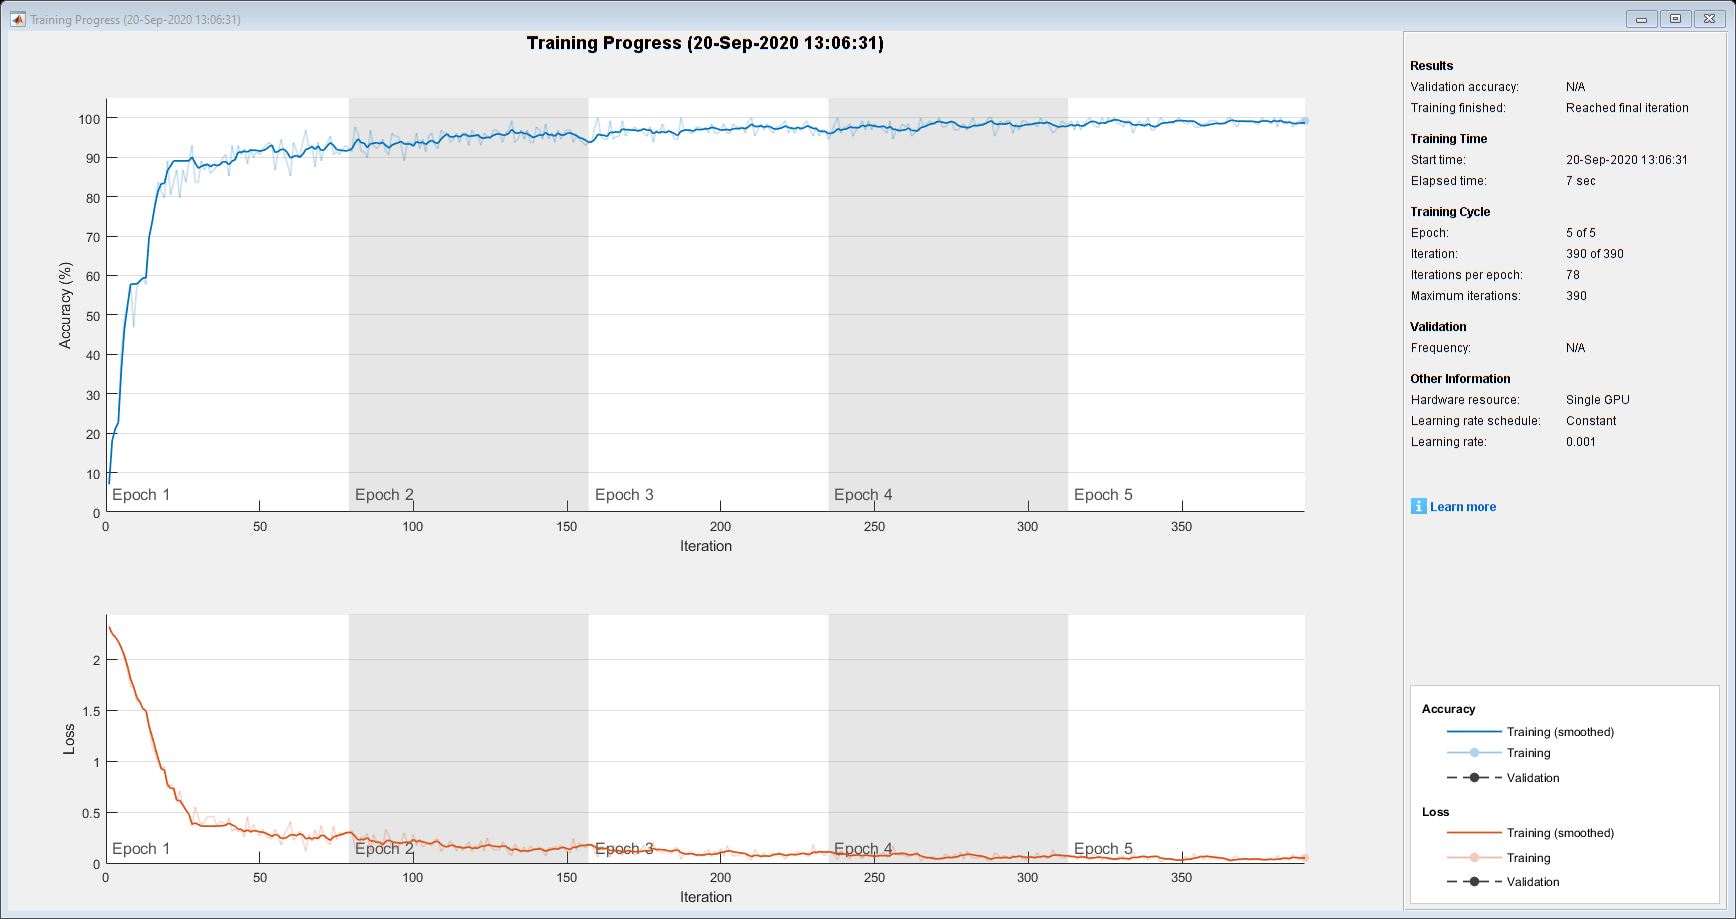

net = trainNetwork(trainImages, trainLabels, layers, opts);

## Evaluate Model

[preds, scores] = net.classify(testImages);
accuracy = nnz(preds == testLabels) / numel(testLabels)

accuracy = 0.9603

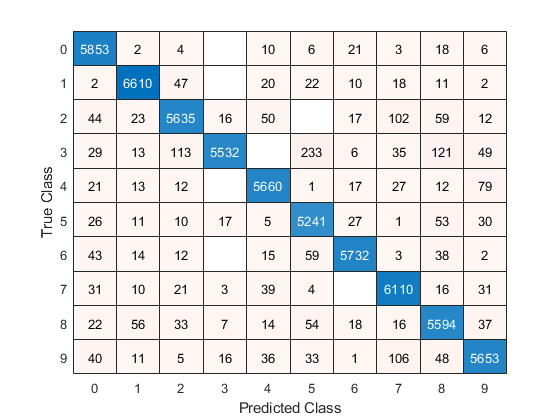

confusionchart(testLabels, preds)

MNIST Dataset file format

- magic number             32 bit integer (identifies whether it is for label or image)

- number of images       32 bit integer

- numRows                    32 bit integer

- numCols                      32 bit integer

function x = readMnistDatasets(filename)
[fileID, errmsg] = fopen(filename, 'r', 'b');
if fileID < 0
    error(errmsg);
end

magicNumber = fread(fileID, 1, 'int32', 0, 'b');
numItems = fread(fileID, 1, 'int32', 0, 'b');
if magicNumber == 2051
    numRows = fread(fileID, 1, 'int32', 0, 'b');
    numCols = fread(fileID, 1, 'int32', 0, 'b');
else
    numRows = 1;
    numCols = 1;
end

x = fread(fileID, inf, 'unsigned char');

x = reshape(x,numCols, numRows, 1, numItems);
end